## Perception 

This diagram shows the steps involve in the object pose estimation using YOLOv4 and PCA based algorithm. 

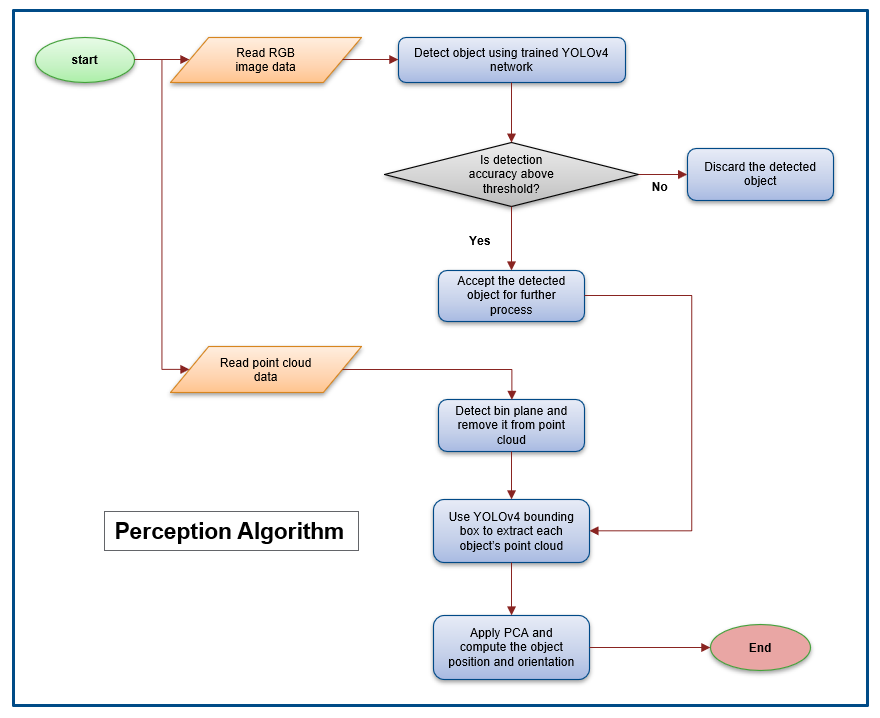

#### Read point cloud and RGB data from the camera sensor

This section creates one additional MATLAB ROS node to communicate with the ROS master to subscribe to the ROS topics for reading the raw RGB and point cloud data.

- The "/camera/color/image_raw" ROS topic is used to read the RGB data.

- The "/camera/depth/color/points" ROS topic is used to read the point cloud data.

Note that "PreserveStructureOnRead" argument is set "true" while reading the data from both the subscriber to preserve the original data size (640 x 280).

rgbImgSub = rossubscriber('/camera/color/image_raw','DataFormat','struct');
subi = receive(rgbImgSub);
rgbImage = rosReadImage(subi,"PreserveStructureOnRead",true);

pointCloudSub = rossubscriber('/camera/depth/color/points','DataFormat','struct');
sub = receive(pointCloudSub);
ptCloud = rosReadXYZ(sub,"PreserveStructureOnRead",true);
ptCloud = pointCloud(ptCloud);

#### Detect objects using trained YOLO network

Set `showPartialOutputs `flag to "true" if you want to visualize the output from the YOLO object detector.

showPartialOutputs = true;

Load the pre-trained YOLO object detector. The training script is provided in the **Perception** folder of this project. Run the below-given command if you want to open the training script.

pretrained = load('trainedYOLOv4DetectorSimGazebo_cuboid.mat')

pretrained = struct with fields:
       detector: [1×1 yolov4ObjectDetector]
    elapsedTime: 4.414373506400000e+03
           info: [1×1 struct]


trainedYoloNet = pretrained.detector; %YOLOv4 network

Run the object detector function to detect the object from the input image taken from the IntelRealSense D415 Gazebo camera sensor. The `detectObjectsYoloNet` function is created to perform object detection using the pretrained YOLOv4 model.

Refer to the** Perception** folder to check `detectObjectsYoloNet` function definition.

[bboxes,scores,labels] = detectObjectsYoloNet(trainedYoloNet,rgbImage);

'detectObjectsYoloNet' is not found in the current folder or on the MATLAB path, but exists in:
    W:\Working_Folder\23b\IBP\MATLAB Project_22b\Perception
    W:\Working_Folder\23b\IBP\bin-picking-gazebo-simulation\Project folder (23a)\Perception

Change the MATLAB current folder or add its folder to the MATLAB path.

Visualize the output from YOLOv4 detector with` rgbImage` data.

if(showPartialOutputs)
    % visualize the detected object bounding box
    annotatedImage = insertObjectAnnotation(im2uint8(rgbImage), 'Rectangle',...
        bboxes, string(labels)+":"+string(scores),'Color','r');
    figure, imshow(annotatedImage);
end

Choose objects which have a detection confidence score higher than yoloScoreTh for further processing

validIdx = scores > yoloScoreTh;
bboxes = bboxes(validIdx, :);
scores = scores(validIdx);
labels = labels(validIdx);
numObjects = size(bboxes,1);

#### Detect the plane and remove the plane from the point cloud

In this section, `pcfitplane` is used to find the indices of the points which refers to the plane. Then further this result is used to pre-process the point cloud by removing the plane from the original point cloud.

% Find plane and non-plane indices of the points from the point cloud
[param, planeIdx, nonPlaneIdx] = pcfitplane(ptCloud, PlaneThickness, normalvector, maxPlaneTilt);

% Create new point cloud by selecting only plane indices from original
% point cloud
plane = select(ptCloud, planeIdx);

% Create new point cloud by selecting non-plane indices from original
% point cloud
nonPlane = select(ptCloud, nonPlaneIdx);

if(showPartialOutputs)
    figure,pcshow(plane,'ViewPlane','XY');axis on;
end

% Create non-plane mask of the same size as raw input image
[m,n,~] = size(rgbImage);
nonPlaneMask = zeros(m,n);
nonPlaneMask =nonPlaneMask(:);
nonPlaneMask(nonPlaneIdx)= 1;

#### Estimate object poses

Here `findObjectPoses `function is used to compute the pose (Position + Orientation with respect to vertical Z axis) from the detected objects bounding box and pre-processed point cloud. This function uses [pca](https://in.mathworks.com/help/stats/pca.html) function which does Principle Component Analysis (PCA) to find the orientation of the detected object from its extracted point clouds. 

Note that pose is considered as [centerX centerY centerZ rotationZ] which is Position and Orientation with respect to vertical Z axis. 

Also note that the computed pose is with respect to the camera frame. 

% Compute the object pose from YOLO output
[xyz,theta,ptCloudVector,ptCloudParameterVector] = findObjectPosesML(ptCloud,rgbImage, bboxes, gridDownsample, nonPlaneMask);

% Visualize computed PCA
if(showPartialOutputs)
    figure;
    for idx = 1: numObjects
        U = ptCloudParameterVector{idx}.UVW(:,1);
        V = ptCloudParameterVector{idx}.UVW(:,2);
        W = ptCloudParameterVector{idx}.UVW(:,3);
        centerOfObject = ptCloudParameterVector{idx}.centroid;
        nexttile;
        pcshow(ptCloudVector{idx},'ViewPlane','XY');
        hold on;
        quiver3(centerOfObject(1), centerOfObject(2), centerOfObject(3), U(1), V(1), W(1), 'r');
        quiver3(centerOfObject(1), centerOfObject(2), centerOfObject(3), U(2), V(2), W(2), 'g');
        quiver3(centerOfObject(1), centerOfObject(2), centerOfObject(3), U(3), V(3), W(3), 'b');
        hold off;
    end
end

Compute object orientation with respect to robot coordinate system using the rotation matrix.

thetaNew = zeros(numObjects,1);
for idx = 1:numObjects
    U = ptCloudParameterVector{idx}.UVW(:,1);
    V = ptCloudParameterVector{idx}.UVW(:,2);
    W = ptCloudParameterVector{idx}.UVW(:,3);
    majorAxis = [U(1), V(1), W(1)];
    majorAxis = (rotationFromRobotToCam*majorAxis')';
    %This calculates the angle between the positive y axis ([ 0 1 0]) and the major axis of the object in an anti-clockwise direction
    thetaNew(idx) = atan2d(dot([0 0 1],cross([  0 1 0],majorAxis)),dot([ 0 1 0],majorAxis));
    if (thetaNew(idx)<0)
        thetaNew(idx) = 180 + thetaNew(idx);
    end
end

#### Create PartGT from the PCA output

Use parameter rotation matrix and camera translation to compute the compute final part ground truth `partGT `for motion planning.

partGT = zeros(numObjects,4);

for i=1:length(ptCloudParameterVector)
    partGT(i,1:3) = rotationFromRobotToCam*xyz(i,:)' + posDepthCam';
    partGT(i,4) = thetaNew(i);
end